# Academic network evolution

## Creating a random adjacency matrix

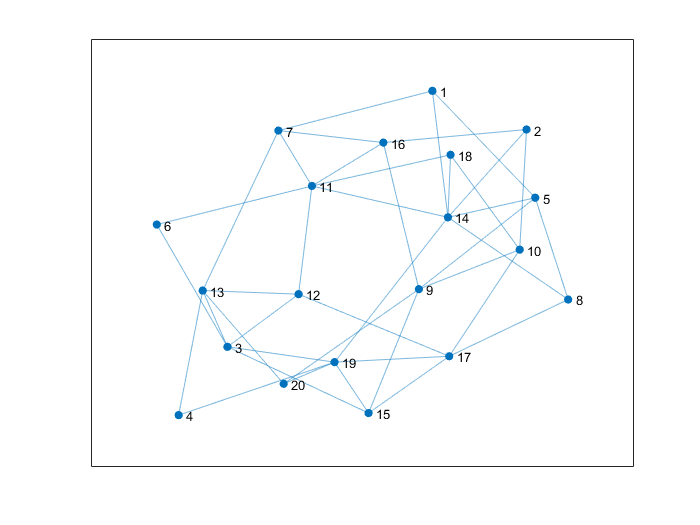

%% Sparse random matrix generation method
A = sprand(v,v,0.002);

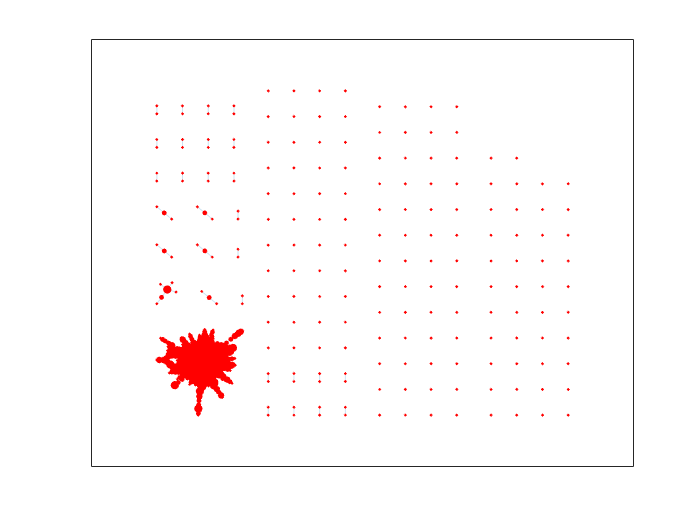

A = round(A + A');
G = graph(A,'omitselfloops');
p=plot(G,'Layout','force','EdgeAlpha',0.2,'NodeColor','r');
deg_ranks = centrality(G,'degree',"Importance",G.Edges.Weight);
edges = linspace(min(deg_ranks),max(deg_ranks),7);
bins = discretize(deg_ranks,edges);
p.MarkerSize = bins;

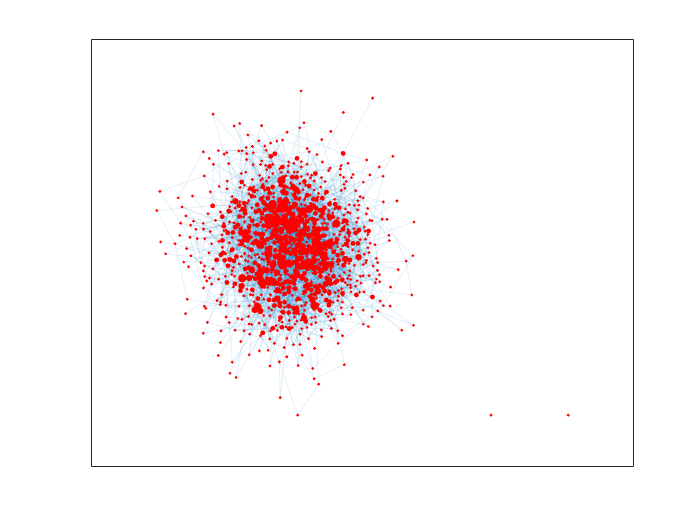

% Algorithm 2 (The Erdos-Renyi G(v,p) model): https://www.geeksforgeeks.org/how-to-create-a-random-graph-using-random-edge-generation-in-java/
maxNodes = 1000;
v = maxNodes; % Could be randomized
p = 0.006; % Could be randomized
A = zeros(v, v);
for i = 1:v
    for j=i+1:v
        if rand<p
            A(i,j)=1;
            A(j,i)=1;
        end
    end
end
G = graph(A,'omitselfloops');
p=plot(G,'Layout','force','EdgeAlpha',0.1,'NodeColor','r');
deg_ranks = centrality(G,'betweenness');
edges = linspace(min(deg_ranks),max(deg_ranks),7);
bins = discretize(deg_ranks,edges);
p.MarkerSize = bins;

% Give them ages
G.Nodes.ID = (1:maxNodes)';
G.Nodes.Age = 40.*(deg_ranks)./max(deg_ranks)+10;
% This keeps track of whether the Agents are active in the research
% community or not
G.Nodes.Activity = ones(maxNodes,1); %1 => active 1= alive, 0 = dead.
G.Nodes.Centrality = deg_ranks;
% Your power, is the average of your centrality and your top 3 neighbours
% centrality
for i = 1:1:maxNodes
    G.Nodes.Power(i)=calculate_power(G, i, deg_ranks);
end

G.Nodes.Tenure = zeros(maxNodes,1);
G.Nodes.Contract = ones(maxNodes,1); % Everyone starts with a contract
for i =1:1:maxNodes
    if G.Nodes.Age(i)<=5
        G.Nodes.Level(i) = 1; % Graduate student
    elseif G.Nodes.Age(i)<=20
        G.Nodes.Level(i) = 2; % Post-doc
    else
    G.Nodes.Level(i) = 3; % Established reseacher
    G.Nodes.Tenure(i) = 1; % Initially all established researchers have tenure
    end
end


simYears = 100;

ans =          0
         0
         0
         0
         0
         0
         0
    0.4545
         0
    0.7273


for i = 1:1:simYears
    % Staying in the field and leaving it depends on power
    G.Nodes.Centrality = centrality(G,'betweenness');
    for j=1:1:numNodes
        % Regreshing Power Distribution
        G.Nodes.Power(j)=calculate_power(G, j, G.Nodes.Centrality);
        % Life
        
        % Contract creation
        if G.Nodes.Age>5 && ~mod(G.Nodes.Age,2) && ~G.Nodes.Tenure && rand < G.Nodes.Power(j)/max(G.Nodes.Power)
            G.Nodes.Contract(j) = 1;
            % Searching for power people who are willing to accept you
            for k=1:1:numNodes
                if G.Nodes.Power(k)>G.Nodes.Power(j) && rand < G.Nodes.Power(j)/max(G.Nodes.Power(j))
                    tempAcceptance(k) = 1;
                else
                    tempAcceptance(k) = 0;
                end
            end
            % Node that you finally select to make a contract with is the
            % most powerful of those who gave you an acceptance
                G.Nodes.Power(tempAcceptance)
        end
        
        % Death
        
        % Death from the field
        % estimated 50% of PhD candidates do not finish
        
    end
    
end


G.Nodes.Age

ans =     4.1667
    4.1667
    4.1667
    4.1667
    4.1667
    4.1667
    4.1667
   25.0000
    4.1667
   37.5000


## Learning

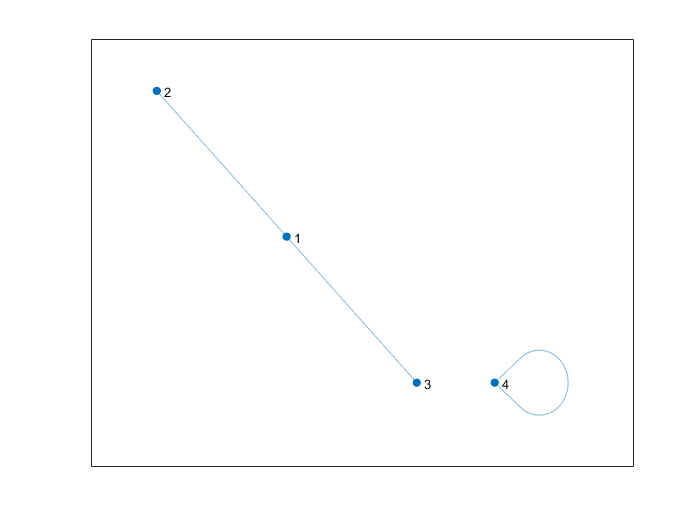

clear all;
G = graph([1 1 4], [2 3 4]);
figure; plot(G)

e = G.Edges; 
G = addedge(G,2,3)

G =   graph with properties:

    Edges: [4×1 table]
    Nodes: [4×0 table]


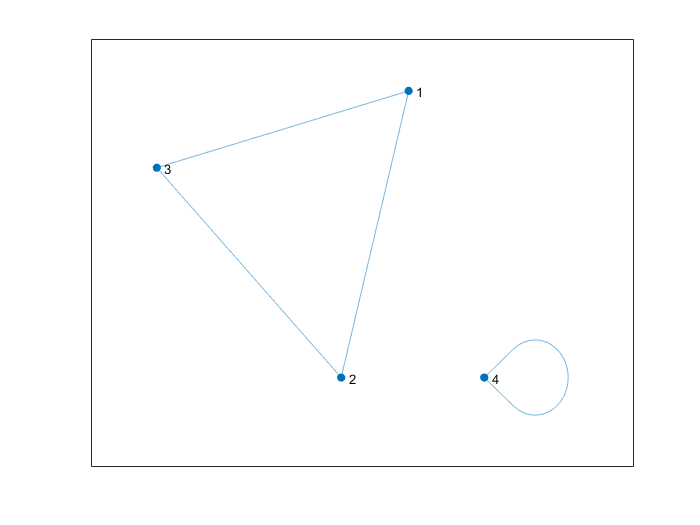

figure; plot(G)

G = addnode(G,1)

G =   graph with properties:

    Edges: [4×1 table]
    Nodes: [5×0 table]


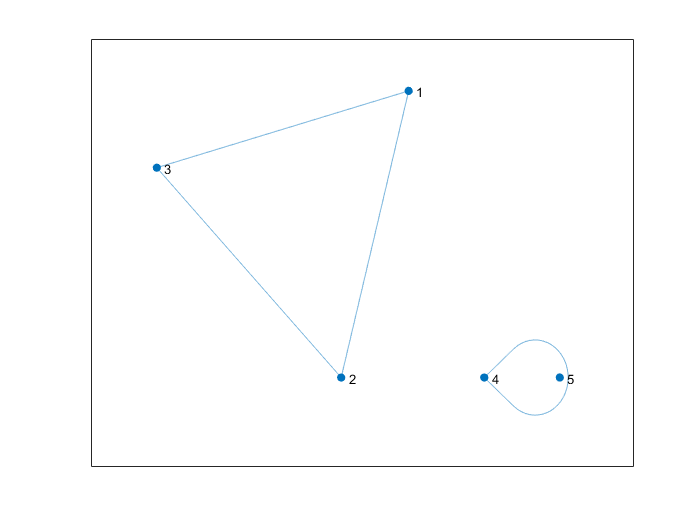

figure; plot(G)

A = adjacency(G)

A =    (2,1)        1
   (3,1)        1
   (1,2)        1
   (3,2)        1
   (1,3)        1
   (2,3)        1


B = full(A)

B =      0     1     1     0
     1     0     1     0
     1     1     0     0
     0     0     0     0


calculate_power(G, 141, deg_ranks)

ans = 2.1059e+03

## Functions

function power=calculate_power(G, NodeID, deg_centrality)
    N=neighbors(G,NodeID);
    tempPower=sort(deg_centrality(N),'desc');
    if length(N)>3
        power = (deg_centrality(NodeID) + sum(tempPower(1:3)))./4;
    else
        power = (deg_centrality(NodeID) + sum(tempPower(1:length(N))))./(length(N)+1);
    end   
end